# Fundamentals of Image and Video Processing

## Screw Detection

Import the input files

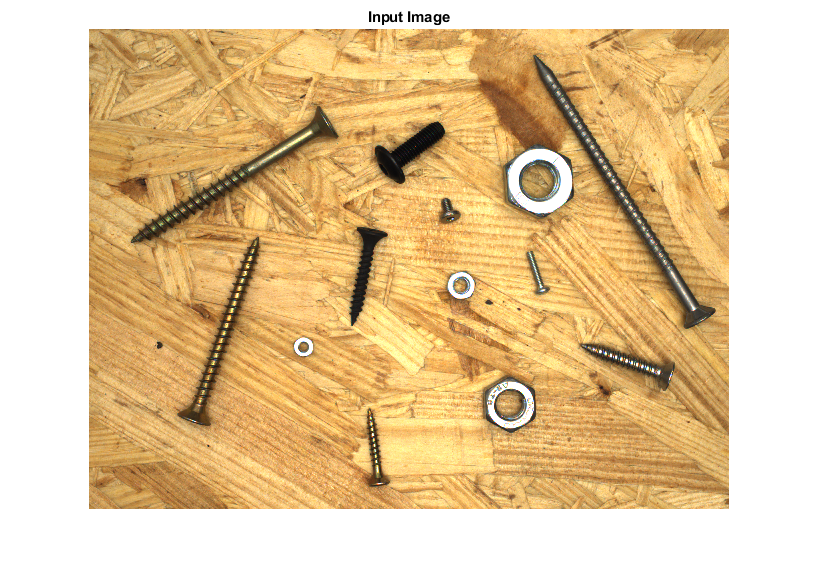

filename = 'images/screws_190.png';
   img = imread(filename);
imshow(img);
title('Input Image');

Threshholding to remove background.

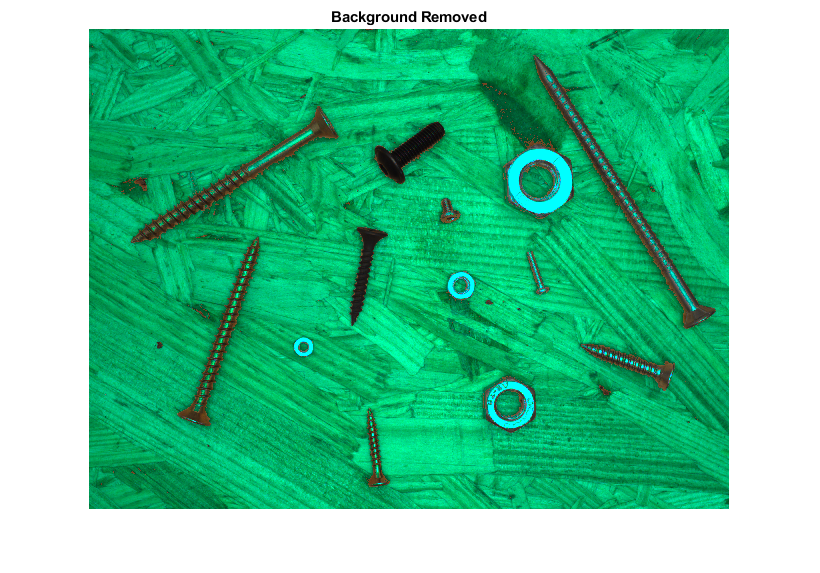

temp1 = img;
for i=1:1440
    for j=1:1920
        for k = 1:3
        if temp1(i,j,1)>120 %Red colour range for background
               temp1(i,j,1)= 0;
        end
        end
    end
end
imshow(temp1);title('Background Removed');

Now to separate screws from other components we will again threshhold as per required.

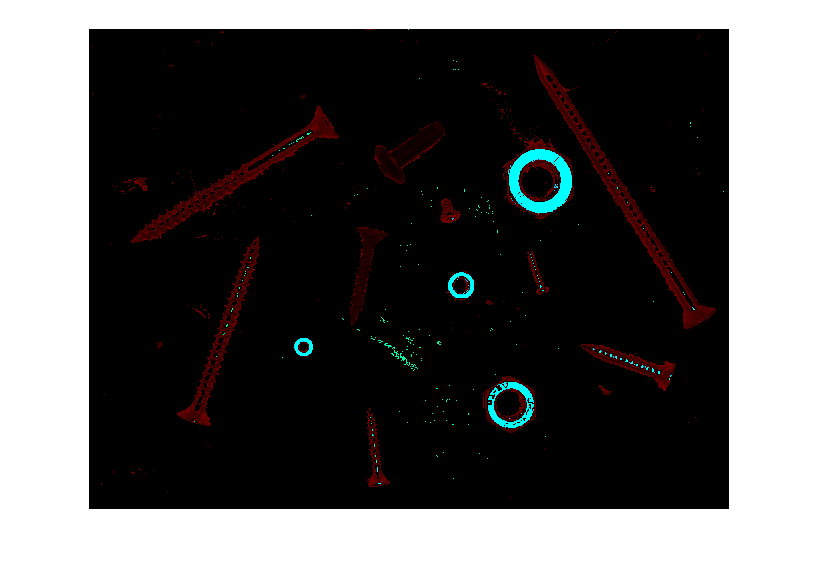

for i=1:1440
    for j=1:1920
        for k = 1:3
         if temp1(i,j,2)<255 && temp1(i,j,3)<255
            temp1(i,j,2)= 0;
            temp1(i,j,3)= 0;
         end
         
       end
    end
end
imshow(temp1)

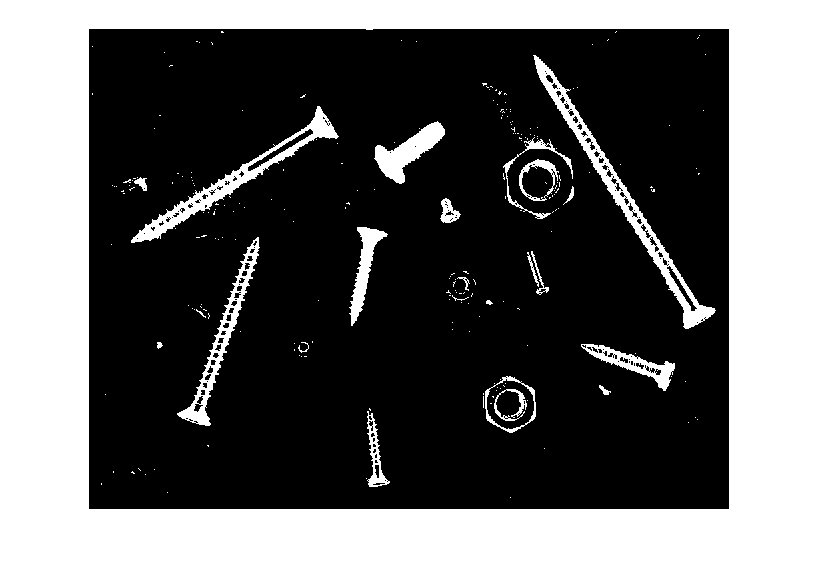

bw = temp1;
for i=1:1440
    for j=1:1920
        for k = 1:3
         if bw(i,j,1)>0
            bw(i,j,1)= 255;
            bw(i,j,2)= 255;
            bw(i,j,3)= 255;
         end
        if bw(i,j,1) ~= 255 || bw(i,j,2) ~= 255 || bw(i,j,3)~=255
        bw(i,j,k) = 0;
        end
        end
        
    end
end
imshow(bw)

Now Binary image is obtained which separated screws and background.Screw shown in white and other things are shown in black.

bw = im2uint8(bw);
bw = imgaussfilt(bw);
bw = im2bw(bw);
bw1 = bw;
% SE1 = 1%strel('line',200,40);
% bw = bwhitmiss(bw,SE1);
bw = ordfilt2(bw,9,ones(13,13));

Tried different filter to smoothen the image. Now we will find edges using Canny edge detection and then identify lines using hough transform.

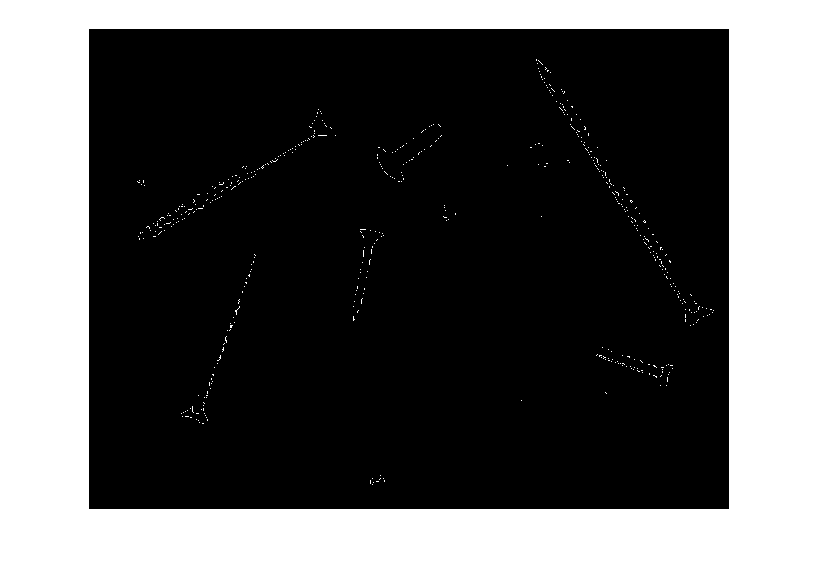


bw = edge(bw);
imshow(bw);

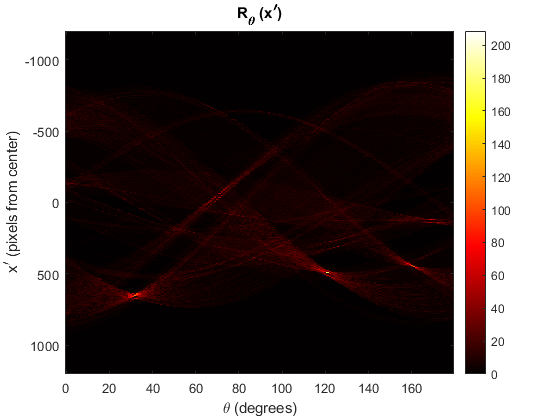

theta = 0:179;
[R,xp] = radon(bw,theta);
figure
imagesc(theta, xp, R); colormap(hot);
xlabel('\theta (degrees)');
ylabel('x^{\prime} (pixels from center)');
title('R_{\theta} (x^{\prime})');
colorbar

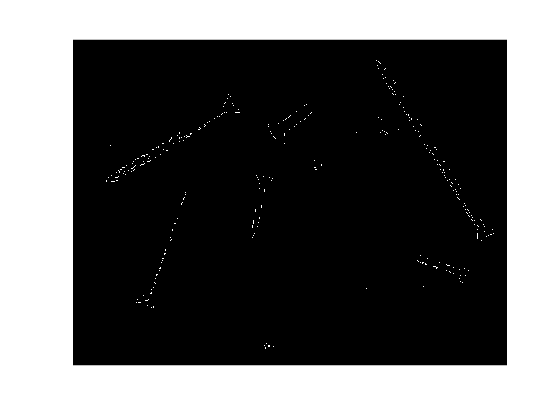

% [H,T,R] = hough(bw,'Theta',-90:1:89,'RhoResolution',1);
% P = houghpeaks(H,6,'threshold',0.60,'NHoodSize',[7 9]);             
% lines = houghlines(bw,T,R,P,'FillGap',5000,'MinLength',40); 
imshow(bw)

% 
% for 
% final = insertText(I,position,numericValue)

After Identifying lines to visualize it we will plot it on image.

% hold on
% for ii = 1:length(lines)                                            
% 	xy = [lines(ii).point1; lines(ii).point2];                         
% 	plot(xy(:,1),xy(:,2),'LineWidth',2,'Color','green');
% end

Results are ready.

Equation of detected lines is saved in workspace.